# **Trabalho 1 de AM2 - Interface Live Script**


addpath './Métodos'
clear;
cla;
clc;

%  ______   _   _   _____ 
%  | ___ \ | | | | |_   _|
%  | |_/ / | | | |   | |  
%  |  __/  | | | |   | |  
%  | |     \ \_/ /  _| |_ 
%  \_|      \___/   \___/ 

% Resolução de Problemas de Valor Inicial
% com recurso a Métodos Numéricos

escolha = "Euler";

syms y(t);

s  =  "y*t^2+y";
a  =  1;
b  =  1.5;
n  =  20;
y0 =  2;
f = @(t,y) eval(vectorize(s));


# **Verificação do Input**


try
    f(t,y);
catch
    errordlg("Introduza uma função em t e y","Erro");
    return
end

$$ans(t) = y\left(t\right)+t^{2}\,y\left(t\right)$$

if (not(isscalar(a) && isreal(a)))
    errordlg("O número introduzido para a é inválido","Erro");
    return
end

if (not(isscalar(b) && isreal(b) && b>a))
    errordlg("O número introduzido para b é inválido","Erro");
    return
end

if (not(isscalar(n) && isreal(n)))
    errordlg("O número introduzido para n é inválido","Erro");
    return
end

if (not(isscalar(y0) && isreal(y0))) 
    errordlg("O número introduzido para y0 é inválido","Erro");
    return
end


# **Solução Exata**


xExata = dsolve(diff(y,t)==f(t,y),y(a)==y0);
g = @(t) eval(vectorize(char(xExata)));
h = (b-a)/n;
t = a:h:b;
yExata = g(t);
plot(yExata,'-r');
hold("on");


# **Método**


switch escolha
    case "Euler"
        sol = MEuler(f,a,b,n,y0)
        plot(sol,'-b');
        legend('Exata','Euler');
        hold("on");
    case "Euler+"
        sol = MEulerMelhorado(f,a,b,n,y0)
        plot(sol,'-b');
        legend('Exata','Euler+');
        hold("on");
    case "RK2"
        sol = NRK2(f,a,b,n,y0)
        plot(sol,'-b');
        legend('Exata','RK2');
        hold("on");
    case "RK4"
        sol = NRK4(f,a,b,n,y0)
        plot(sol,'-b');
        legend('Exata','RK4');
        hold("on");
    case "ODE45"
        sol = ode45(f,[a b],y0)
        plot(sol.y,'-b');
        legend('Exata','ODE45');
        hold("on");
    case "PSM"
        %%%%%%%
    case "Todos"
        Euler = MEuler(f,a,b,n,y0);
        EulerM = MEulerMelhorado(f,a,b,n,y0);
        RK2 = NRK2(f,a,b,n,y0);
        RK4 = NRK4(f,a,b,n,y0);
        ODE45 = ode45(f,[a b],y0).y;


# **Tabela**

        
        tabela = [t.',yExata.',Euler.',EulerM.',RK2.',RK4.'];
        array2table(tabela,"VariableNames",{'t','Exata','Euler','Euler+','RK2','RK4'})
        array2table(ODE45.',"VariableNames",{'ODE45'})

# **Gráfico**

        
        title('Gráfico das soluções da PVI');
        plot(Euler);
        plot(EulerM);
        plot(RK2);
        plot(RK4);
        plot(ODE45);
        legend('Exata','Euler','Euler+','RK2','RK4','ODE45');
        hold("on");
        
        

# **Soluções**

        
        disp("SOLUÇÃO EXATA:    " + yExata(end));
        disp("Solução Euler:    " + Euler(end));
        disp("Solução Euler+:   " + EulerM(end));
        disp("Solução RK2:      " + RK2(end));
        disp("Solução RK4:      " + RK4(end));
        disp("Solução ODE45:    " + ODE45(end));
        

# **Iterações**

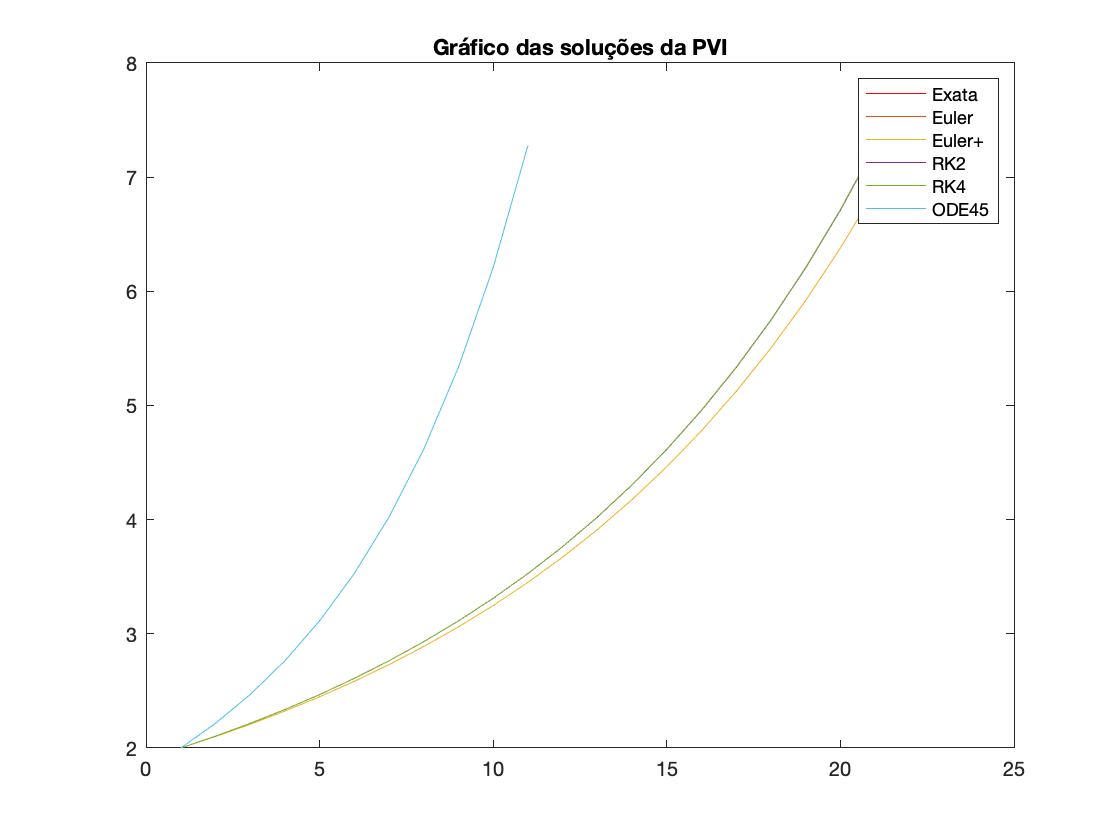

ans = 21×6 table
      t      Exata     Euler     Euler+     RK2       RK4  
    _____    ______    ______    ______    ______    ______

        1         2         2         2         2         2
    1.025    2.1039       2.1       2.1    2.1038    2.1039
     1.05     2.216    2.2077    2.2077    2.2159     2.216
    1.075    2.3371    2.3237    2.3237     2.337    2.3371
      1.1    2.4682    2.4489    2.4489     2.468    2.4682
    1.125    2.6102    2.5842    2.5842    2.6099    2.6102
     1.15    2.7643    2.7306    2.7306    2.7639    2.7643
    1.175    2.9316    2.8891    2.8891    2.9311    2.9316
      1.2    3.1137    3.0611    3.0611    3.1131    3.1137
    1.225    3.3121    3.2478    3.2478    3.3113    3.3121
     1.25    3.5284    3.4509    3.4509    3.5275    3.528

ans = 11×1 table
    ODE45 
    ______

         2
     2.216
    2.4682
    2.7643
    3.1137
    3.5284
    4.0235
    4.6179
     5.336
    6.2091
    7.2777


SOLUÇÃO EXATA:    7.2777


Solução Euler:    6.8859


Solução Euler+:   6.8859


Solução RK2:      7.2715


Solução RK4:      7.2777


Solução ODE45:    7.2777


Iterações Euler:    21


Iterações Euler+:   21


Iterações RK2:      21


Iterações RK4:      21


Iterações ODE45:    11


        fprintf('\n ')
        disp("Iterações Euler:    " + length(Euler));
        disp("Iterações Euler+:   " + length(EulerM));
        disp("Iterações RK2:      " + length(RK2));
        disp("Iterações RK4:      " + length(RK4));
        disp("Iterações ODE45:    " + length(ODE45));
    
end